## Load Necessary Saved Data

clear; clc; close all;
try
    loadData = load("C:\Users\seane\OneDrive\Documents\College\Saved_Runs\ASML_EC_Sim_Run_zeroShot_Target4_23_Feb_2023_15_29_17.mat");
catch
  [fname,fpath] = uigetfile('C:\Users\seane\OneDrive\Documents\College\Saved_Runs\','Select a dataset');
  loadData = load(fullfile(fpath,fname));
  disp(['Selected ', fullfile(fpath,fname)]);
end
logsout = loadData.logsout;
ec = loadData.ec;
clear loadData fpath fname;



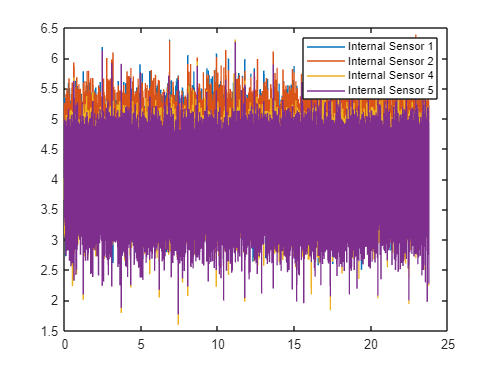

clsource1 = logsout.Ecl_Source1;
clsource2 = logsout.Ecl_Source2;
clsource4 = logsout.Ecl_Source4;
clsource5 = logsout.Ecl_Source5;
clscanner = logsout.Ecl_Scanner;

clsource1 = clsource1(clsource1 > 0);
clsource2 = clsource2(clsource2 > 0);
clsource4 = clsource4(clsource4 > 0);
clsource5 = clsource5(clsource5 > 0);
clscanner = clscanner(clscanner > 0);

t = logsout.T_Ecl_Scanner(1:1188543);

cov_coef12 = corrcoef(clsource1,clsource2);
cov_coef14 = corrcoef(clsource1,clsource4);
cov_coef15 = corrcoef(clsource1,clsource5);
cov_coef24 = corrcoef(clsource2,clsource4);
cov_coef25 = corrcoef(clsource2,clsource5);
cov_coef45 = corrcoef(clsource4,clsource5);

cov_coef1o = corrcoef(clsource1,clscanner);
cov_coef2o = corrcoef(clsource2,clscanner);
cov_coef4o = corrcoef(clsource4,clscanner);
cov_coef5o = corrcoef(clsource5,clscanner);



figure(2)
plot(t,clsource1)
hold on
plot(t,clsource2)
plot(t,clsource4)
plot(t,clsource5)
legend('Internal Sensor 1','Internal Sensor 2','Internal Sensor 4','Internal Sensor 5')